% Create a patchMicrostrip antenna
% Generated by MATLAB(R) 9.6 and Antenna Toolbox 4.0.
% Generated on: 13-Jun-2019 10:47:39

## Antenna Properties

Design antenna at frequency 77000000000Hz

antennaObject = design(patchMicrostrip,77000000000);
% Update substrate properties 
antennaObject.Substrate.Name = 'Air';
antennaObject.Substrate.EpsilonR = 1;
antennaObject.Substrate.LossTangent = 0;
antennaObject.Substrate.Thickness = 3.89340854545455e-05;

## Antenna Analysis

Define plot frequency 

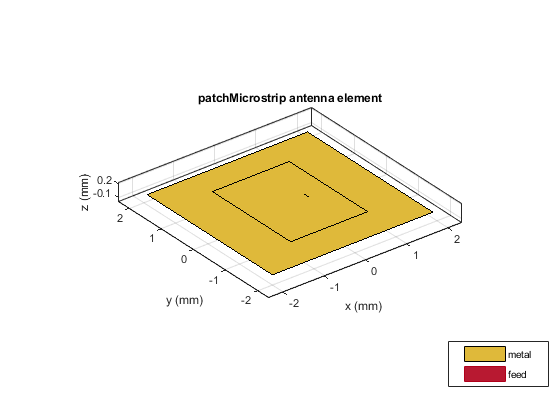

plotFrequency = 77000000000;
% Define frequency range 
freqRange = (69.3:0.77:84.7) * 1e9;
% show for patchMicrostrip
figure;
show(antennaObject) 

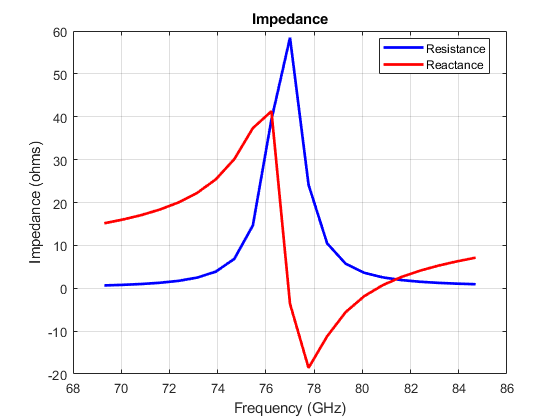

% impedance for patchMicrostrip
figure;
impedance(antennaObject, freqRange) 

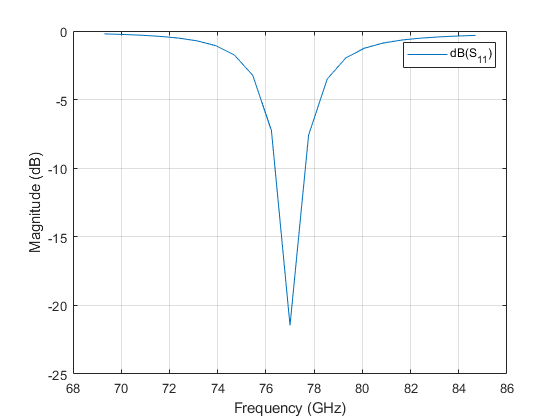

% s11 for patchMicrostrip
figure;
s = sparameters(antennaObject, freqRange); 
rfplot(s) 

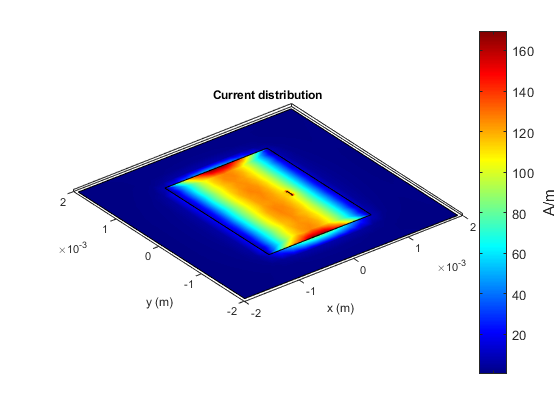

% current for patchMicrostrip
figure;
current(antennaObject, plotFrequency) 

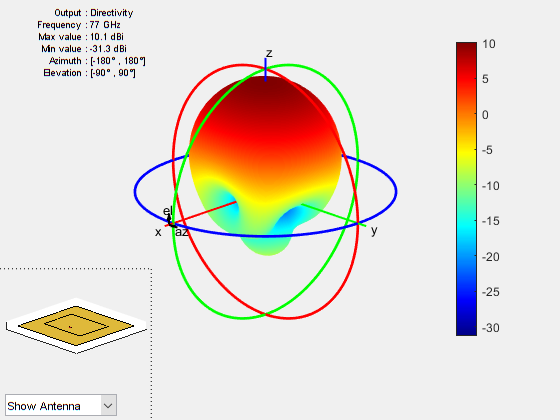

% pattern for patchMicrostrip
figure;
pattern(antennaObject, plotFrequency) 

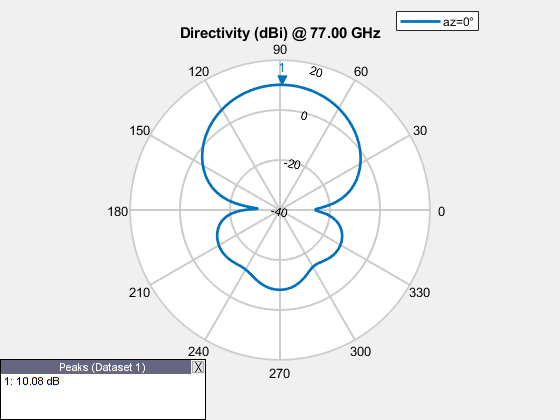

% elevation for patchMicrostrip
figure;
patternElevation(antennaObject, plotFrequency)